clc
data=load('data.txt')

data =     20    25    60    70
    35    30    65   105
    40    34    75   135
    50    37    80   170


% Create a plot of the data
xt=(data);
yt=xt(:);
% k impair
% Define the parameters
k = 7;  % value of k
m = (k-1)/2;  % value of m
T=length(yt);
% Calculate the rolling mean using the formula
pair_rolling_means=zeros(T-k+2,1);
for i=k:T
    t_prime=sum(i-(k-1):i)/k
    pair_rolling_means(i) = (sum(yt(t_prime-m:t_prime+m))) / k;    
end

t_prime = 4

t_prime = 5

t_prime = 6

t_prime = 7

t_prime = 8

t_prime = 9

t_prime = 10

t_prime = 11

t_prime = 12

t_prime = 13

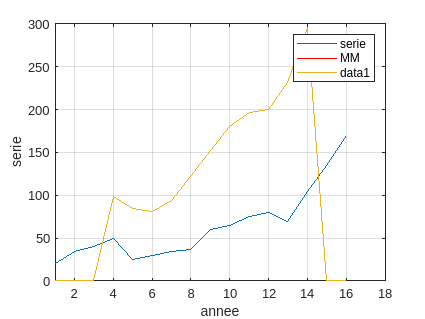

figure
plot(yt);
xlim([1 T+2])
xlabel('annee');
ylabel('serie');
hold on;
x2=k-3:T-3;
plot(x2,rolling_means(k-3:T-3),'r');
legend('serie','MM');
grid on;
plot(rolling_means)